%ПИД-регулятор kp = 0.5, ki = 10, kd = 0.1
% Constants
ke = 0.4987;
km = ke;
Tm = 0.0886;  
R =  8.8696;
L = 0.0047;
J = 0.0023;
target = 400;
U = 8.05;
M = 0.02; 

kp= 0.5; 
ki= 10; 
kd = 0.1;

data=readmatrix('Files_PID\PID_kp0.5_ki10_kd0.1.txt');
X=data(:,1);
Y=data(:,2);

Y_fixed=Y(length(Y))

Y_fixed = 592

e_fixed='Nan'

e_fixed = 'Nan'

overshoot='Nan'

overshoot = 'Nan'

t_transition='Nan'

t_transition = 'Nan'

xlim([0 20])
simout=sim('PID_model')

simout =   Simulink.SimulationOutput:

            simulinkPID: [1x1 timeseries] 
                   tout: [11439x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


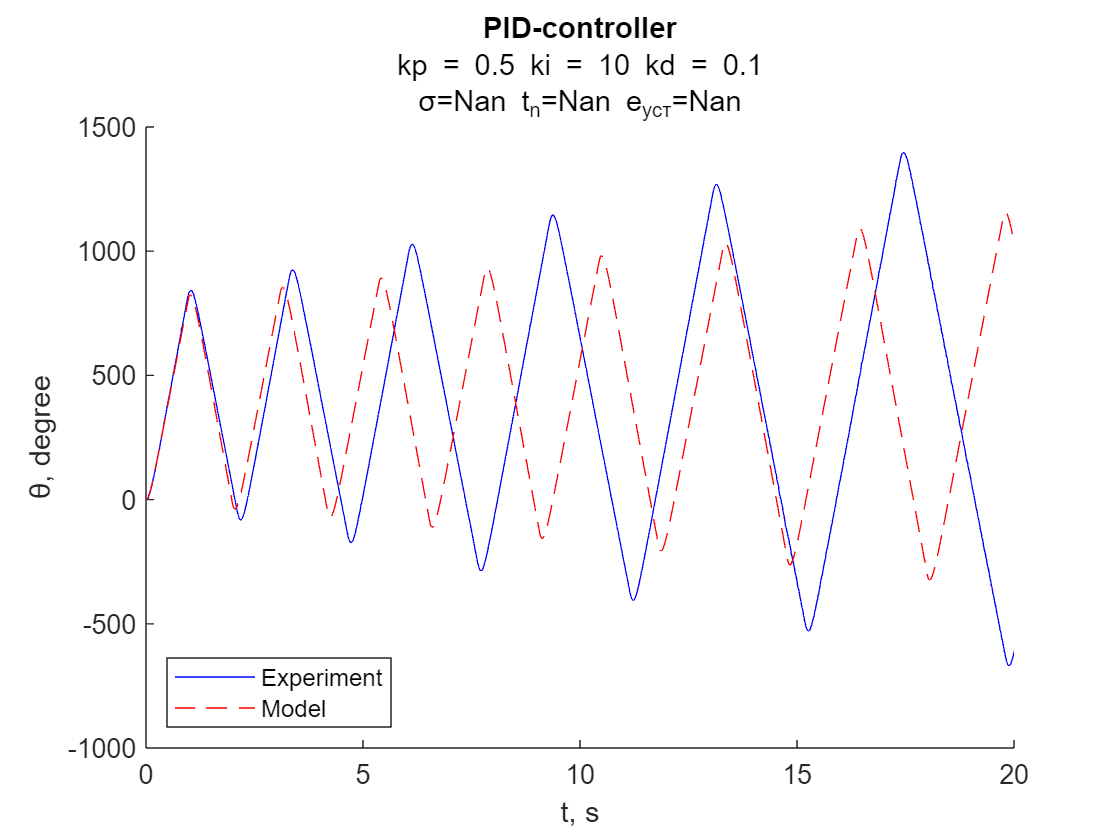



hold on
plot(X,Y,'b')
plot(simout.simulinkPID.Time, simout.simulinkPID.Data,'r--')
h2 = strcat('σ=',string(overshoot), ' t_{n}=', string(t_transition),' e_{уст}=', string(e_fixed));
title('PID-controller',{'kp = 0.5 ki = 10 kd = 0.1',h2})
xlabel('t, s')
ylabel('θ, degree')
legend('Experiment', 'Model','Location','southwest')